# Generation of steering file - unit test

## Structure

The  - `generateStf.m` function gets three objects input arguments (no values are assigned inside the function):

- Information about the ct voxels `ct`

- The classification of these voxels into different organs and tissue` cst`

- Informaion about the radiation treatment plan` pln`

It the output is the `stf`  struct with the following fields: 

- target volume:           voxel coordnates of target

- template:                   3xN array with 2D template point unit positions

- radiation mode:         string `'brachy'`

- needle info:               needle information: seed number and distance

- orientation:                unit vectors of final template position and offset

- seed info:                  Source information relevant for dose calculation

- seed positions:           3D array with dimentions (needle number, seed number, coord in mm)

## Tests and visual control

### 1 Seed positions array size

assert(size(stf.seedPos,1) == width(stf.template.template2D),'needle no does not match');
assert(size(stf.seedPos,2) == stf.needle.seedsNo, 'wrong seed no');
assert(size(stf.seedPos,3) == 3,'lenth of position vector is not three');

### 2 Check seed points for Orthogonality

limit = 1e-10;
assert(permute((stf.seedPos(1,1,:)-stf.seedPos(1,2,:)),[1,3,2])*permute((stf.seedPos(1,1,:)-stf.seedPos(2,1,:)),[3,2,1]) < limit,...
    'rotated seeds not orthogonal')

### 3 Visual check

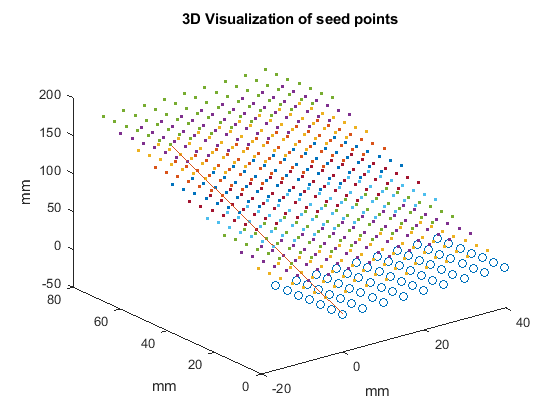

%rotated template
clf
template3D = stf.template.template3D;
plot3(template3D(1,:),template3D(2,:),template3D(3,:),'o');
hold on
%Z direction
seeds = stf.seedPos;
Zvec = zeros(3,2);
for i = 1:3
    Zvec(i,:) = [stf.orientation.offset(i),stf.orientation.offset(i)+stf.needle.seedDistance*stf.needle.seedsNo*stf.orientation.Zdir(i)];
end
plot3(Zvec(1,:),Zvec(2,:),Zvec(3,:))
%3D seed positions
plot3(seeds(:,:,1),seeds(:,:,2),seeds(:,:,3),'.')
title( '3D Visualization of seed points')
xlabel('mm')
ylabel('mm')
zlabel('mm')